# Homework 2

The influence of backlash in a control system will be discussed in this homework. Consider the drive line in a crane, where torque is generated by an electric motor, transformed through a gearbox, and finally used to lift a load. A block diagram describing the control of the angular position (aka, angular displacement) of the lifting axis $\theta_{out}$ is shown below. Here the first block represents the P-controller ($G_{e \rightarrow V} = K >0$), the second the dynamics in the motor ($G_{V \rightarrow \omega_{in}} = \frac{1}{T s + 1}$, with $T>0$), and the third the back-lash between the gear teeth in the gearbox (there is a dynamic relation between the angular velocity of the driving gear and the angular velocity of the driven gear).

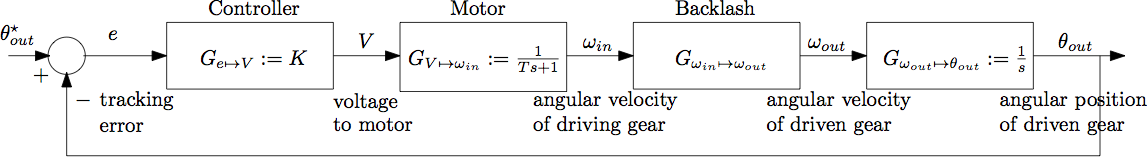

Due to the backlash, rather than an identity map from the angular displacement of the driving gear (aka$\theta_{in}$) to the angular displacement of the driven gear (aka$\theta_{out}$), there is a dynamic relation between those. Consider then the backlash as the relation between the angular velocities $\omega_{in}$ and $\omega_{out}$,


$$\dot{\theta}_{out} 
= 
\omega_{out}(\theta_{out},\theta_{in},\omega_{in}) 
=
\begin{cases}
\omega_{in}
&
\text{if contact}(\theta_{out},\theta_{in},\omega_{in})
\\
0 & \text{otherwise} 
\end{cases} $$


where 


$$\text{contact}(\theta_{out},\theta_{in},\omega_{in}) 
= \text{True} 
\text{ if } 
| \theta_{in} - \theta_{out}| \ge \Delta
\wedge 
\omega_{in}(\theta_{in} - \theta_{out}) > 0,
\\
\text{contact}(\theta_{out},\theta_{in},\omega_{in}) 
= \text{False} 
\text{ otherwise}.$$


## 1 [1p]

Consider the back-lash model described as a block

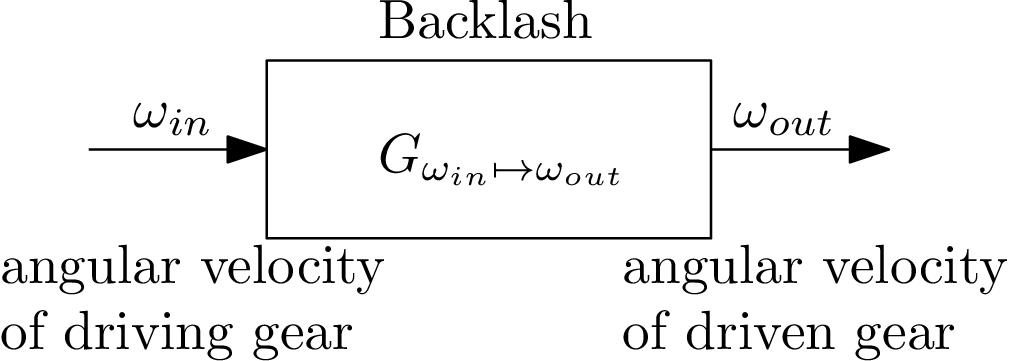

Take 


$$\omega_{in}:
R_{\ge 0} \ni t 
\mapsto 
\omega_{in}(t) = \begin{cases}
\,\,\, 1  & t \in [0,1)
\\
-1 & t \in [1,2)
\\
0 & t \in [2,\infty)
\end{cases}$$


as the input to the BL model (in open-loop). Sketch $\theta_{in}$, $\theta_{out}$, $\omega_{in}$, and $\omega_{out}$ for $(\theta_{in}(0),\theta_{out}(0)) = (0,-\Delta)$ in a diagram. You may take $\Delta = 1$ degree, which means the driving gear can move $2\Delta=2$ degrees, while the drived gear stays at rest (experiment with other values for $\Delta$ if necessary).

The systematic scheme in Simulink looks like below

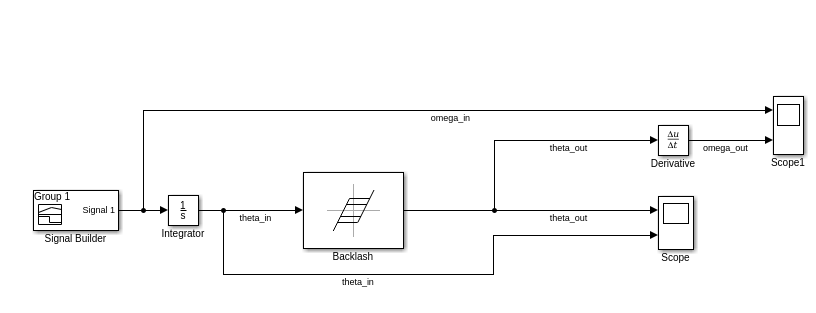

where a Signal Builder is used to generate the input signal. Just to simplicity. I could just define the sequences but I think that this would be simplier to work with but the principle  is the same.

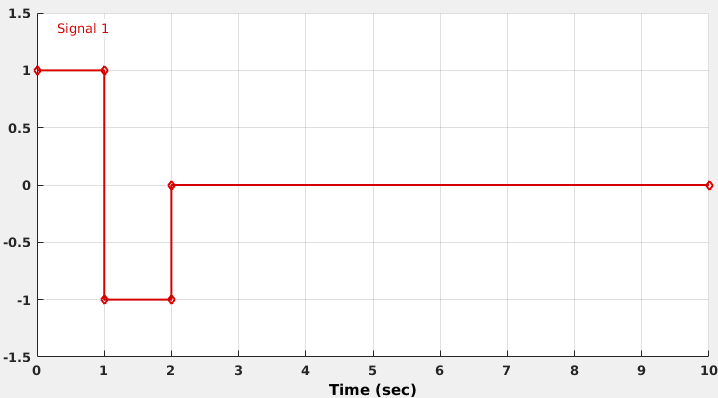

The output of $\omega_{in}$ and $\omega_{out}$ is shown down. The x-axis show the time in [sec]

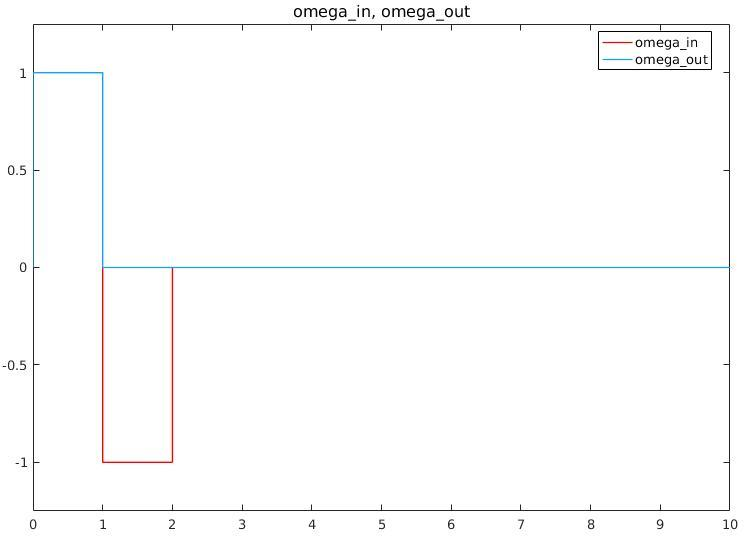

$\theta_{in}$ and $\theta_{out}$ shows below

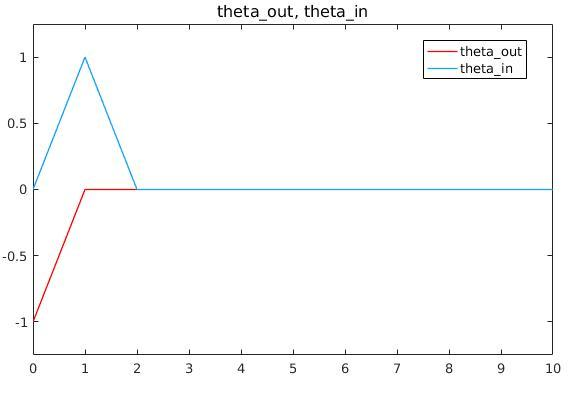

## 2.1[1p]

Show that the gain of the BL system is unitray, i.e., that $\gamma(G_{\omega_{in} \rightarrow \omega_{out}})=1$. Show that the BL system is passive. Motivate why the BL system is bounded by a sector $[k_1,k_2] = [0,1]$.  Assume the condition above.

Regarding passivity we have, this with regards to 


$$\text{contact}(\theta_{out},\theta_{in},\omega_{in}) 
= \text{True} 
\text{ if } 
| \theta_{in} - \theta_{out}| \ge \Delta
\wedge 
\omega_{in}(\theta_{in} - \theta_{out}) > 0,
\\
\text{contact}(\theta_{out},\theta_{in},\omega_{in}) 
= \text{False} 
\text{ otherwise}.$$


Following is obtained


$${\left\langle u,y\right\rangle }_T =\text{ }\int_0^T u\text{ }y\text{ }dt=\int_0^T u\left\lbrace \begin{array}{c}
u & contant\\
0 & othewise
\end{array}\right.\ge 0$$


when the gears are in contact we have a $\omega_{in\text{ }} =\omega_{out}$ then the equation above garantees that positivness.

Regarding the gain $\gamma$ :


$$\gamma \left(\text{BL}\right)=\sup \frac{\|S\left(u\right)\|}{\|u\|}=\frac{\|\left\lbrace \begin{array}{c}
u & \text{contant}\\
0 & \text{othewise}
\end{array}\|\right.}{\|u\|}=1$$


The relation between $\omega_{in$ and $\omega_{out}$ has a gain of between zero and one. That means that the circle is bounded by


$$k_1 = 0 \rightarrow \frac{-1}{k_1} = -\infty$$



$$k_2 = 1 \rightarrow \frac{-1}{k_2} = -1$$


This garanties the stability of the closed loop system 


$$Re(G(i\omega). C(i \omega)) > -1$$


## 3.1[1p] 

Consider the backlash model BL in a feedback loop,

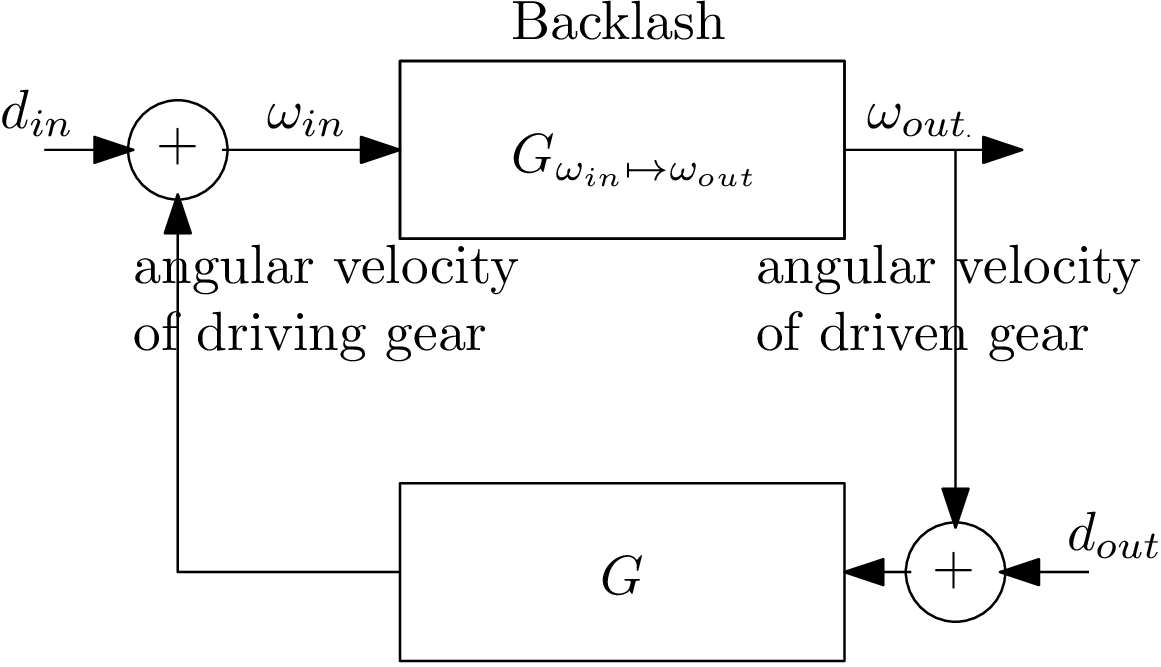

Here $d_{in}$ and $d_{out}$ represent disturbances. Assume that $G(s)$ is an arbitrary transfer function.

## 3.1a [1/3p] 

Given $\gamma(G_{\omega_{in} \rightarrow \omega_{out}})$ derived in Exercise $2$, which constraints are imposed on $G(s)$ by the Small Gain Theorem in order to have a BIBO stable closed-loop system (from ($d_{in}$, $d_{out}$) to $(\dot{\theta}_{in},\dot{\theta}_{out}) = (\omega_{in},\omega_{out})$)?

From SGT


$$\| G \| \| G_{\omega} \| <1$$


and since $\gamma \left(G_{\omega } \right)=1$ from the exercise 2 then we have:


$$\gamma \left(G\left(i\omega \right)\right)∗1<1\to \text{ }\gamma \left(G\left(i\omega \right)\right)<1$$


## 3.1b [1/3p] 

Which constraints are imposed on $G(s)$ by the Passivity Theorem in order to have a BIBO stable closed-loop system?

The closed loop system is BIBO stable if one of the two is strictly passive and the other one is passive. in the case of back lash we saw that 


$${\left\langle u,y\right\rangle }_T =\text{ }\int_0^T u\text{ }\cdot y\text{  }dt=\int_0^T u\cdot \text{ }\left\lbrace \begin{array}{c}
u & if\text{ }\text{ }Contact=true\\
0 & Otherwise
\end{array}\right.\ge 0$$


When the gears are not in contact then we have ${\left\langle u,y\right\rangle }_T =\text{ }{\left\langle \omega_{in} \cdot \omega_{out} \right\rangle }_T =0$ . when on the other side the gears are in contact we have ${\left\langle \omega_{\text{in}} \cdot \omega_{\text{out}} \right\rangle }_T =\omega ²\ge 0$. The system is not strictly passive but is passive. In this case the $G(i\omega)$ has to be strictly passive. This means that if there is $\varepsilon >0$ such thet following is fulfilled


$$Re\left(G\left(j\omega −\varepsilon \right)\right)\ge 0,\forall \omega >0$$


## 3.1c [1/3p] 

Which constraints are imposed on $G(s)$ by the Circle Criterion in order to have a BIBO stable closed-loop system?

We saw that the circle defined in exercise 2 is defined by $k=[0,1]$ that is a cirle in $(- \infty,0), (-1,0)$. the boundry of the cicle is $-1$ and by Circle Criterion $G(i \omega)$ should intersect or be places on the left side of this area. That gives following condition:


$$Re\left(G\left(i\omega \right)\right)>−1,\forall \omega >0$$
 

## 4 [1p]

For the crane control system, the transfer function in Exercise 3 is equal to (take $\theta_{out}^{\star} = 0$)


$$	G =
	G_{V \rightarrow \omega_{in}}( G_{e \rightarrow V } (G_{\omega_{out} \rightarrow \theta_{out} }))
	= 
	G_{V \rightarrow \omega_{in}}
	\cdot
	G_{e \rightarrow V }
	\cdot
	G_{\omega_{out} \rightarrow \theta_{out} } 
	= \frac{K}{s(1+sT)}.$$


Motivate why BIBO stability (from ($d_{in}$, $d_{out}$) to $(\dot{\theta}_{in},\dot{\theta}_{out}) = (\omega_{in},\omega_{out})$, as in Exercise 3) cannot be concluded from the Small Gain Theorem or the Passivity Theorem. Let $T = 1$ and determine for which $K>0$ the Circle Criterion leads to BIBO stability.

Consider the linear system below:


$$\frac{K}{s\left(1+sT\right)}$$


Cosider fourther more the gain of the system


$${sup\left(G\left(i\omega \right)\right)}_{\omega } =\|\frac{K}{i\omega \left(1+i\omega T\right)}\|$$


We see that the gain of the system will tend to $\infty$ when $\omega$ tends to zero which contradicts the result from SGT. According to SGT the gain should not be greater than 1.  According to PT (passivity theorem) we had the conclusion that $Re\left(G\left(i\omega \right)\right)>−1,\forall \omega >0$ in order for the system to be strictly passive. PT gives that the gain of the system should be finite.


$$Re\left(G\left(i\omega \right)\right)=Re\left(\frac{K}{i\omega \left(1+i\omega T\right)}\right)=\left\lbrace T=1\right\rbrace =Re\left(\frac{K}{i\omega \left(1+i\omega \right)}\right)>−1,\forall \omega >0$$



$$\to Re\left(−\frac{K\left(\omega +i\right)}{\omega \left(1+\omega^2 \right)}\right)>−1\to \frac{−K}{1+\omega^2 }>−1$$


As you see that $K<1+\omega^2$ which indicates that K is growing. For $K=0$ the condition above holds since $0>-1$ . For $K\rightarrow 1$ the condition still holds. we bound $K$ by (0,1).

## 5 [1p]

Along with the .mlx file you find a .mdl and a .m file (a simulink file and a script file, respectively). You may open the Simulink model by running 

hw2

After inspection of the block diagram in hw2.mdl, compare that with the block diagram in this homework. What disturbance is added in hw2? What $\Delta$ is chosen? Simulate the system with the controller $K = 0.25$ by running

K=0.25; 
macro

Following graphs are obtained using the commands above

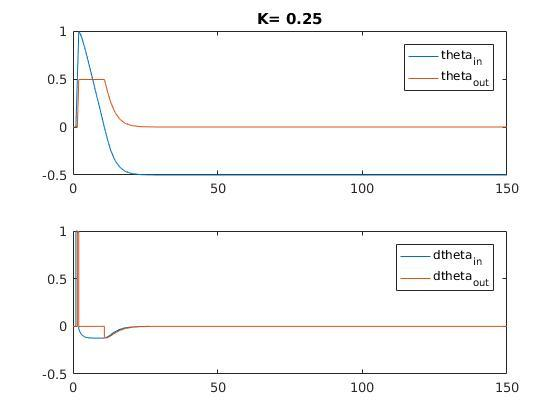

Disturbances are added and as seen in the figure they are between $t =1$ and $2$. $\Delta$ is 0.5.

Does it seem like the closed-loop system is BIBO stable from $d_{in}$ to $(\dot{\theta}_{in},\dot{\theta}_{out})$? Why cannot the closed-loop system be BIBO stable from $d_{in}$ to $(\theta_{in},\theta_{out})$? Try other controller gains (for instance, $K=0.5$ and $K=4$). Compare with your conclusions in Exercise 4. Compare your results to the case when the backlash is neglected.

In exercise $4$ we showed that in order for the system to be BIBO stabe we should have constraints on gain $K$. 

The results from $K = 0.25$ are presented below

For $K=0.5$ we have

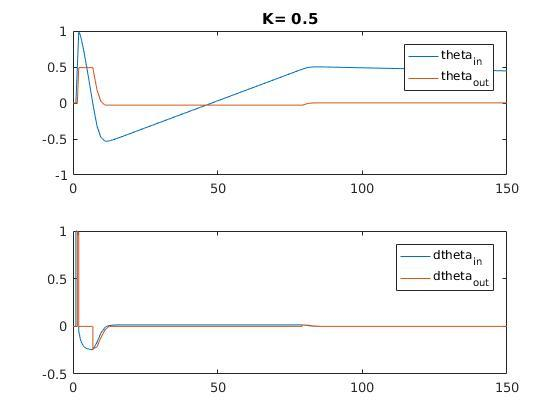

For $K = 4$. system becomes instable since the value of $K$ is not feseable according to exercise 4.

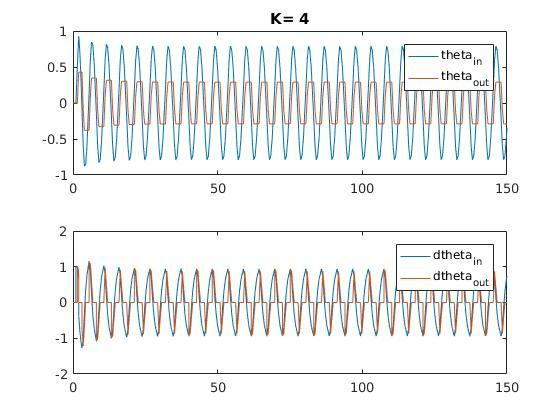

With no Backlash following are obtained

$K=0.25$:

As seen from the figure below we have a overshoot due to the dirturbances.

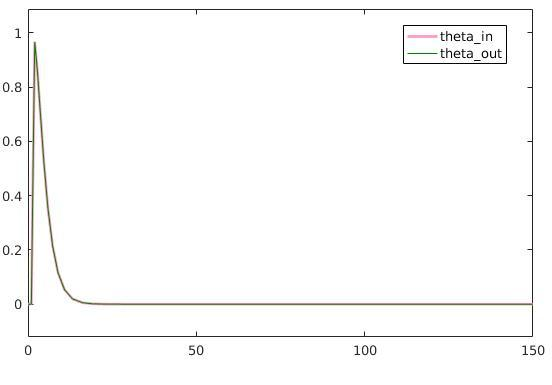

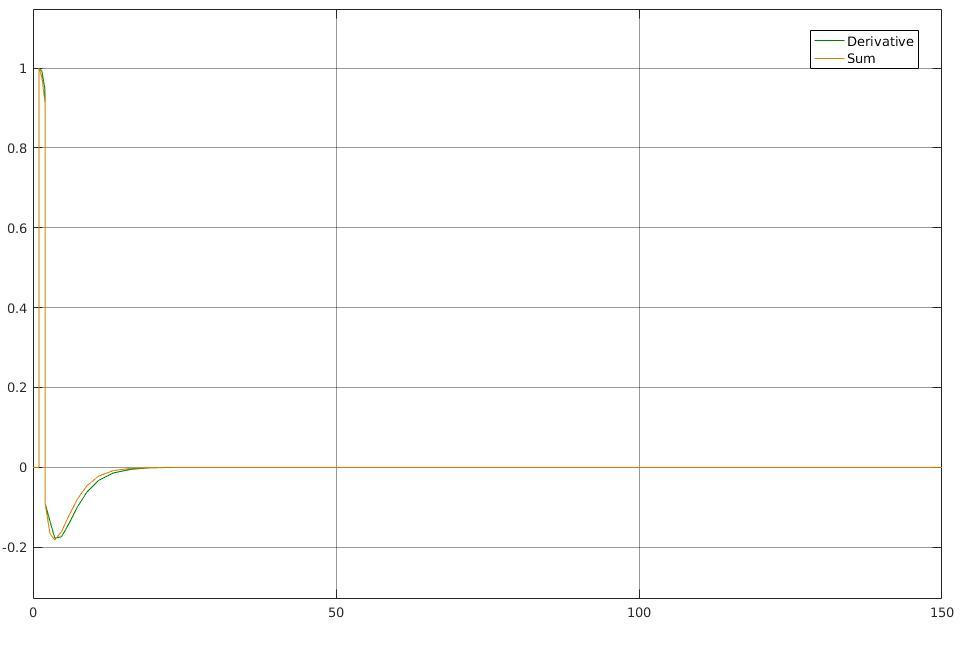

$K=0.5$:

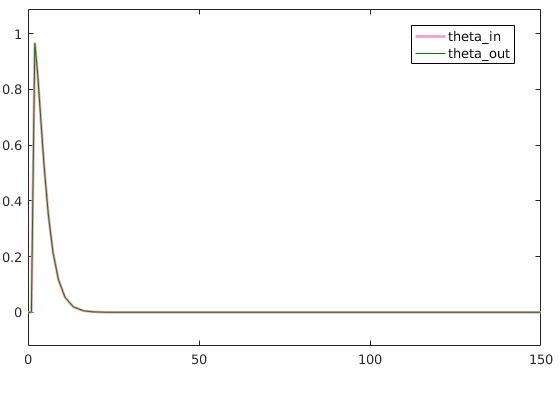

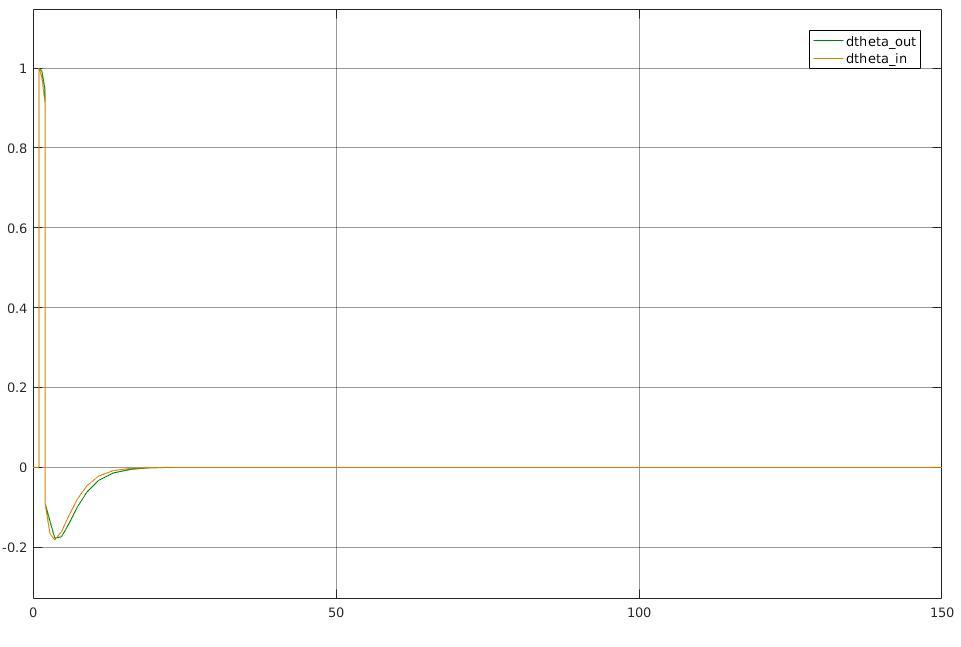

$K=4$: We have an overshoot nd disturbances but at the end the system becomes stable.

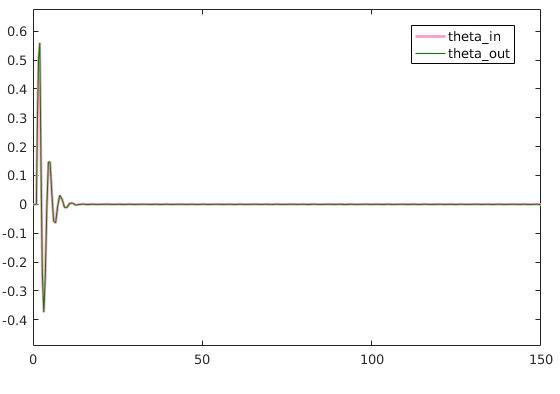

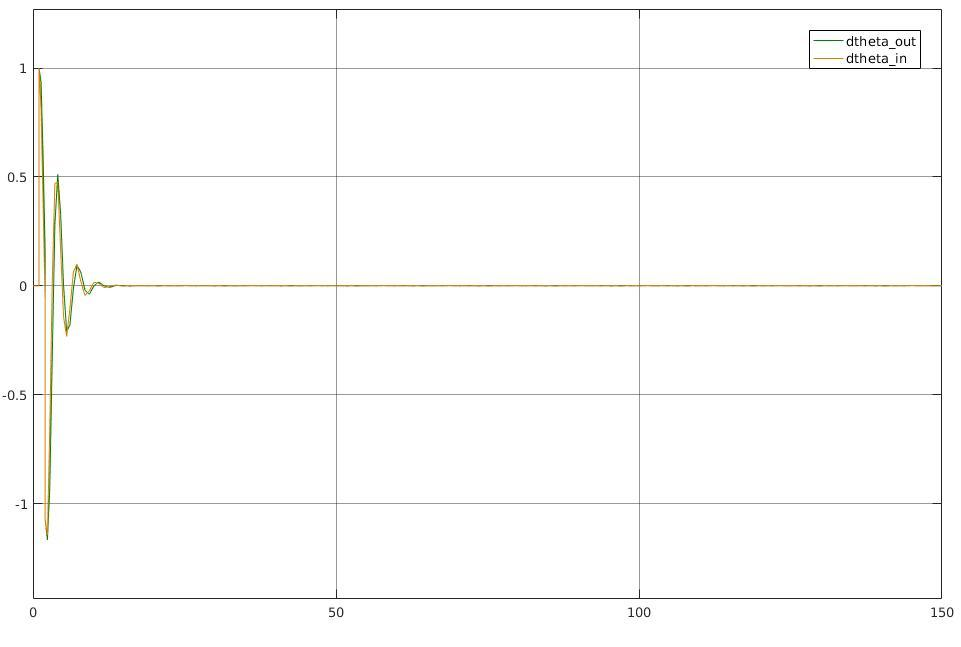

With no Backlash we only intergtate and derivate something. in case of continuous times it should not differ and the output and input should be the same. Due to the PT, now that the BL is neglected we can conclude that the the system $G$ should be passive if 


$$Re\left(G\left(i\omega \right)\right)\ge 0$$


and following the same procedure as earlier and following the schematic in hw2.mdl give that, in order for system to be stricltly passive.


$$Re\left(G\left(i\omega \right)\right)=\frac{K}{\omega^2 +1}>0$$


which is valid for all $K >0$. However for greater K we have oscillations.